Contellations for m=4,16,32 qams.

%qam4 = [-1-1i 1-1i 1+1i -1+1i];
%qam4 = qam4/mean(abs(qam4));
%plot(qam4,'*');
qam16 = [-3-3i -3-1i -3+3i -3+1i -1-3i -1-1i -1+3i -1+1i 3-3i 3-1i 3+3i 3+1i 1-3i 1-1i 1+3i 1+1i];
%qam16 = qam16/mean(abs(qam16));
%plot(qam16,'*');
%qam32 = [-3+7i -1+7i 3+7i 1+7i -3+5i -1+5i 3+5i 1+5i -3+1i -1+1i 3+1i 1+1i -3+3i -1+3i 3+3i 1+3i -3-7i -1-7i 3-7i 1-7i -3-5i -1-5i 3-5i 1-5i -3-1i -1-1i 3-1i 1-1i -3-3i -1-3i 3-3i 1-3i];
%qam32 = qam32/mean(abs(qam32));
%plot(qam32,'*');

Antennas specification and definining the Spatial symbols

Tx=4;
Rx=4;
Nr=Tx-2;
Spr=(mean(abs(qam16)))^2;
SNR=10^(10/10);
sigmaN=Spr/SNR;
Spsym=combnk(1:Tx,Nr);

ber=zeros([1,10000]);
for k=1:length(ber)

modulation of the symbols

    Xm=qam16(randi(16,[Nr,1]));

modulation of spatial bits

    xs=randi(length(Spsym));
    X=zeros([Tx 1]);
    X(Spsym(xs,:))=Xm;

Transmission through channel

    H = sqrt(2)*randn(Rx,Tx) + 1i*sqrt(2)*randn(Rx,Tx);
    Y=H*X + sqrt(sigmaN)*randn([Rx,1]);

Detection using matched filter

    Xcap=pinv(H)*Y;                                %MSME
    %Xcap=((H'*H+(1/SNR)*eye(length(H'*H)))\H')*Y;  %Bayes Regularization
    %Xcap=H'*Y;                                     %matched filter
    clear H Y;
    mm=abs(Xcap);
    [~,thd]=maxk(mm,Nr);
    Xsc=sort(thd);
    %clear mm;
    xscap=find(sum(Spsym-Xsc' ~=0,2) ==0);
    Xmcap=transpose(qam16demod(Xcap(Xsc)));
    clear Xsc;
    be=0;
    if xs~=xscap
        be=be+1;
    end
    be=be+sum(Xm~=Xmcap,2);
    ber(k)=be;
end
clear k be;
disp(mean(ber));

    0.3826



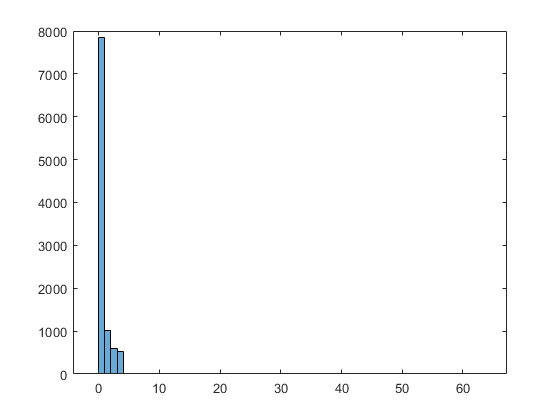

histogram(ber,-1:64)

Demodulation of qam symbols

% function y=qam4demod(x)
% re = quant((real(x)+1),2)-1;
% im = (quant((imag(x)+1),2)-1);
% re(re>1)=1;
% re(re<-1)=-1;
% im(im>1)=1;
% im(im<-1)=-1;
% y=re+im*1i;
% end

function y=qam16demod(x)
re = quant((real(x)+1),2)-1;
im = (quant((imag(x)+1),2)-1);
re(re>3)=3;
re(re<-3)=-3;
im(im>3)=3;
im(im<-3)=-3;
y=re+im*1i;
end
% function y=qam32demod(x)
% re = quant((real(x)+1),2)-1;
% im = (quant((imag(x)+1),2)-1);
% re(re>3)=3;
% re(re<-3)=-3;
% im(im>7)=7;
% im(im<-7)=-7;
% y=re+im*1i;
% end